# BME 3053C Final Project

Group Members: Grace Cabrera, Mahmoud Fakhouri, Isabel Munoz, April Olson

Course: BME 3053C Computer Applications for BME

Term: Fall 2020

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: Grace's, Mahmoud's, Isabel's, aprilolson@ufl.edu

December xx, 2020

Reading Image File

clc; clear; close all;
image = imread('IDRiD_50.jpg');

Extracting Green Channel

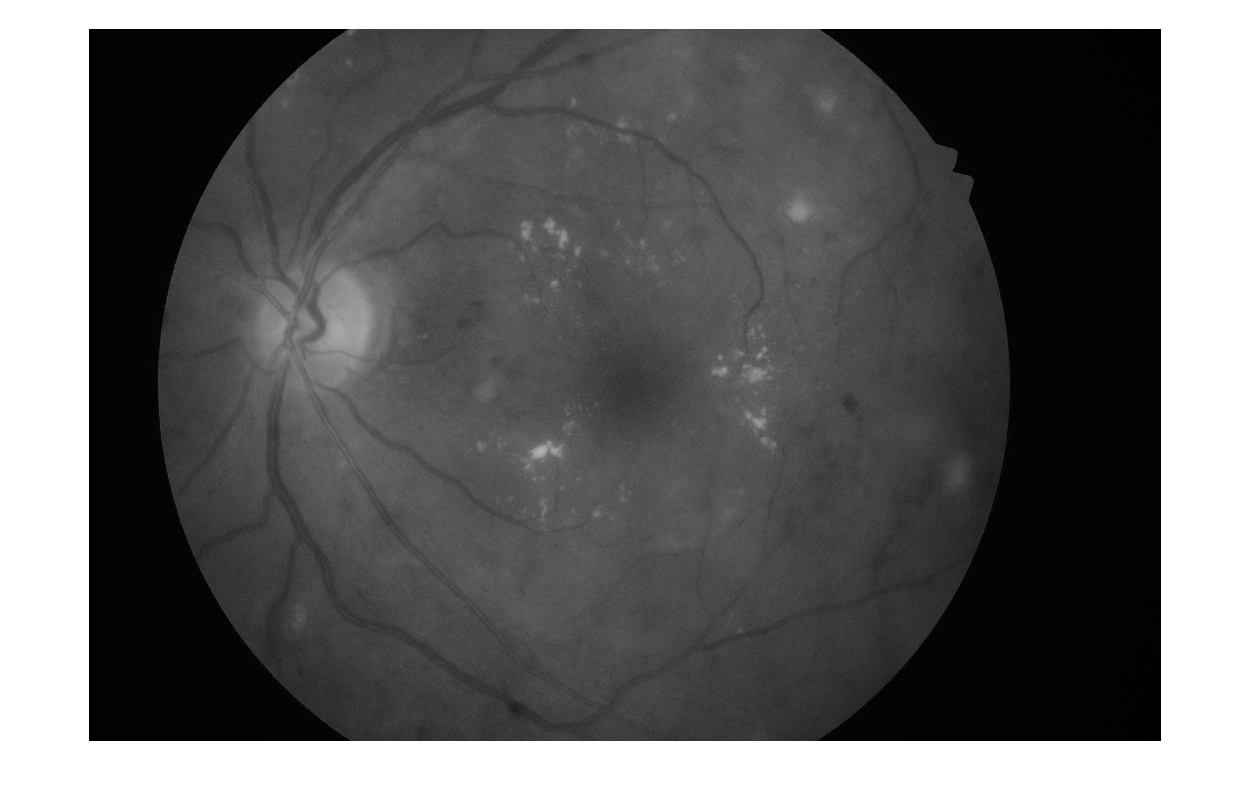

G = image(:,:,2);
imshow(G)

Binarizing Image

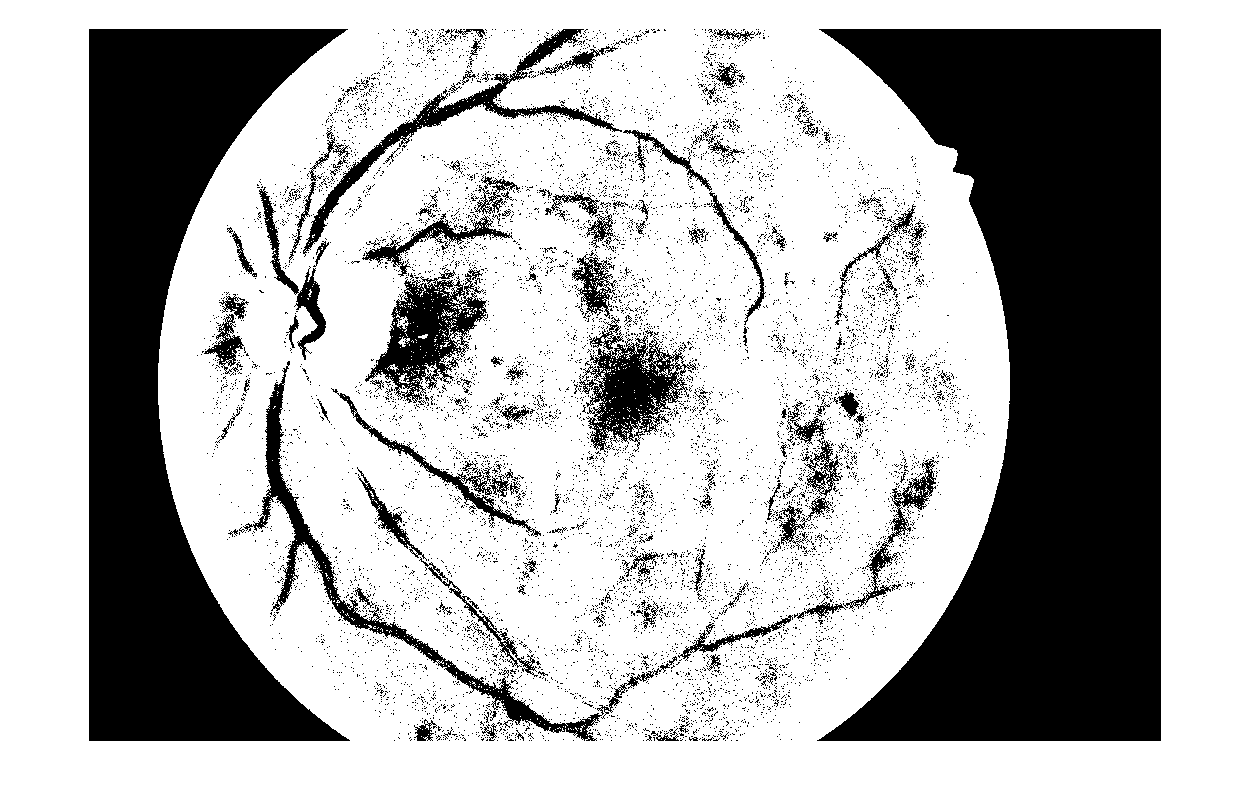

mask = G > 10;
G(~mask) = 0;
I = imbinarize(G,'adaptive','ForegroundPolarity','dark','Sensitivity',0.53);
imshow(I)

Invert Binary Image

I = imcomplement(I);

Dilate

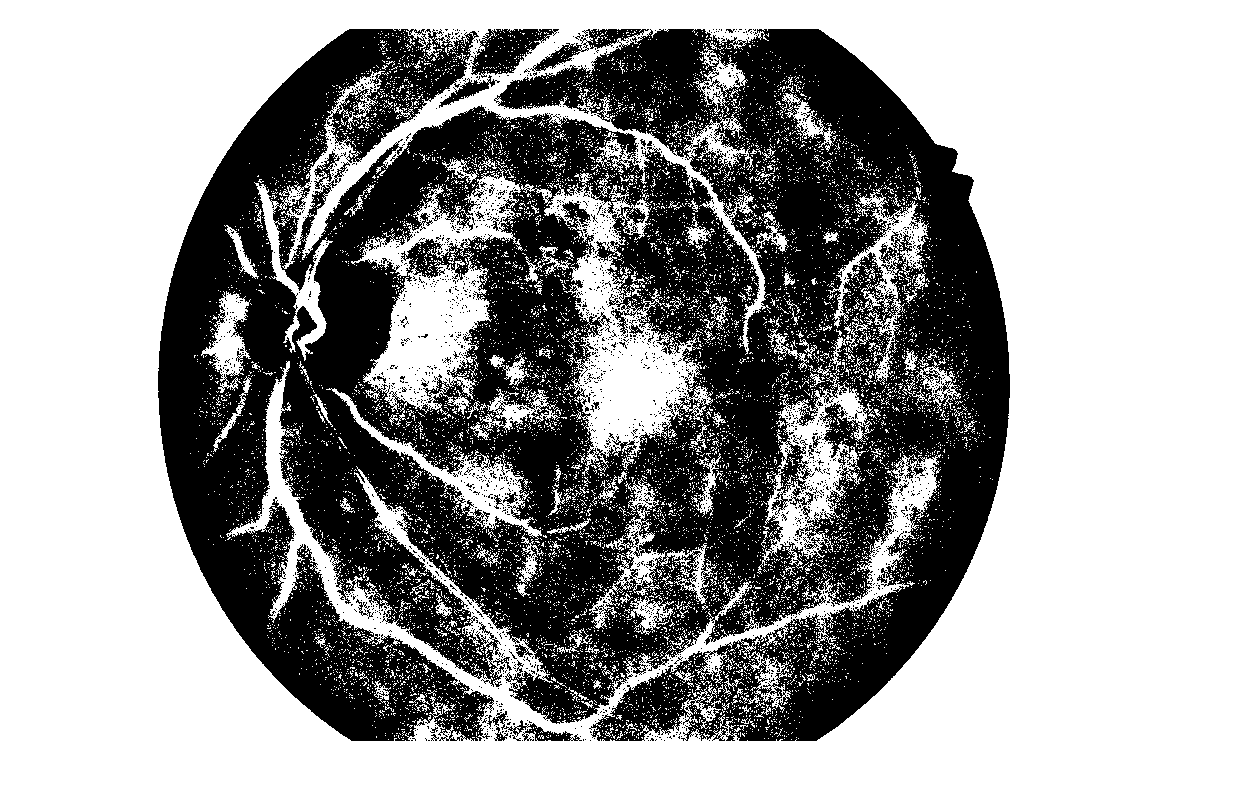

se90 = strel('line',3,90); 
se0 = strel('line',3,0);
I = imdilate(I,[se90 se0]); 
imshow(I)

Fill Holes

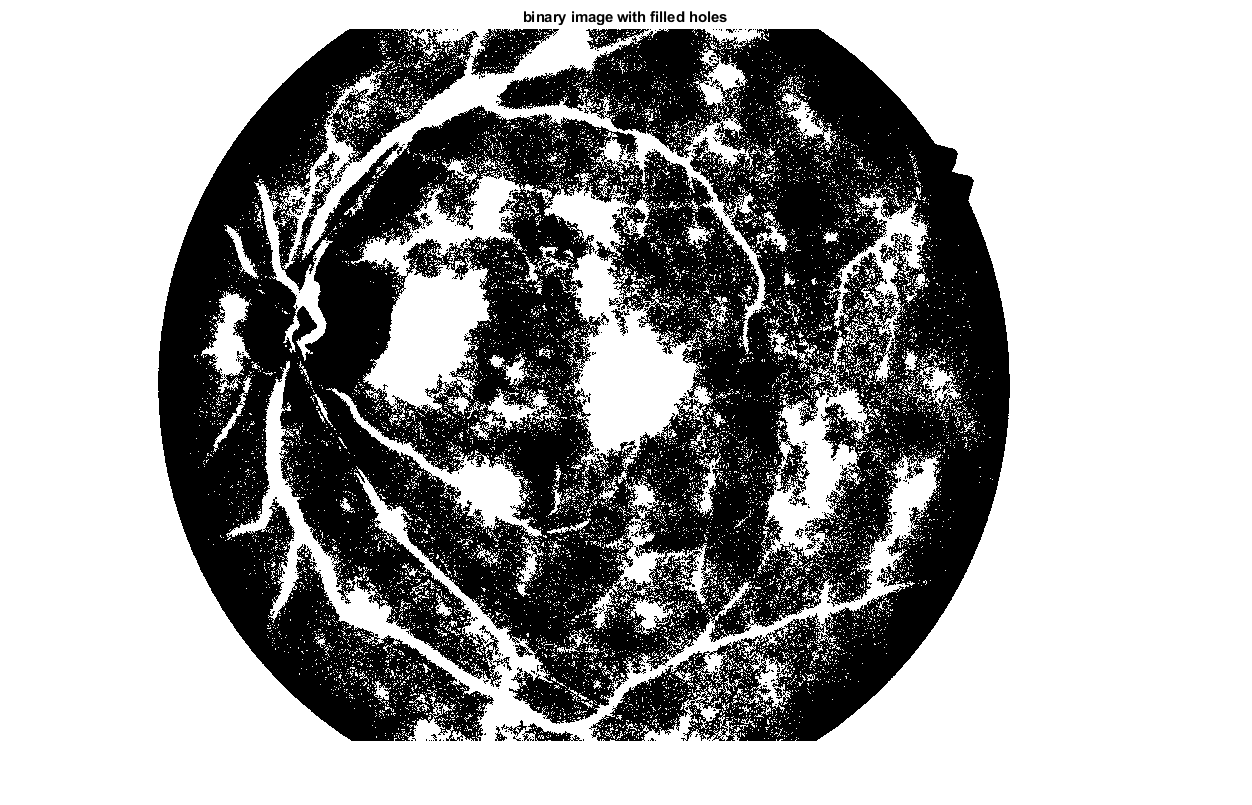

I = imfill(I,'holes'); 
imshow(I);
title('binary image with filled holes')

Clear small areas

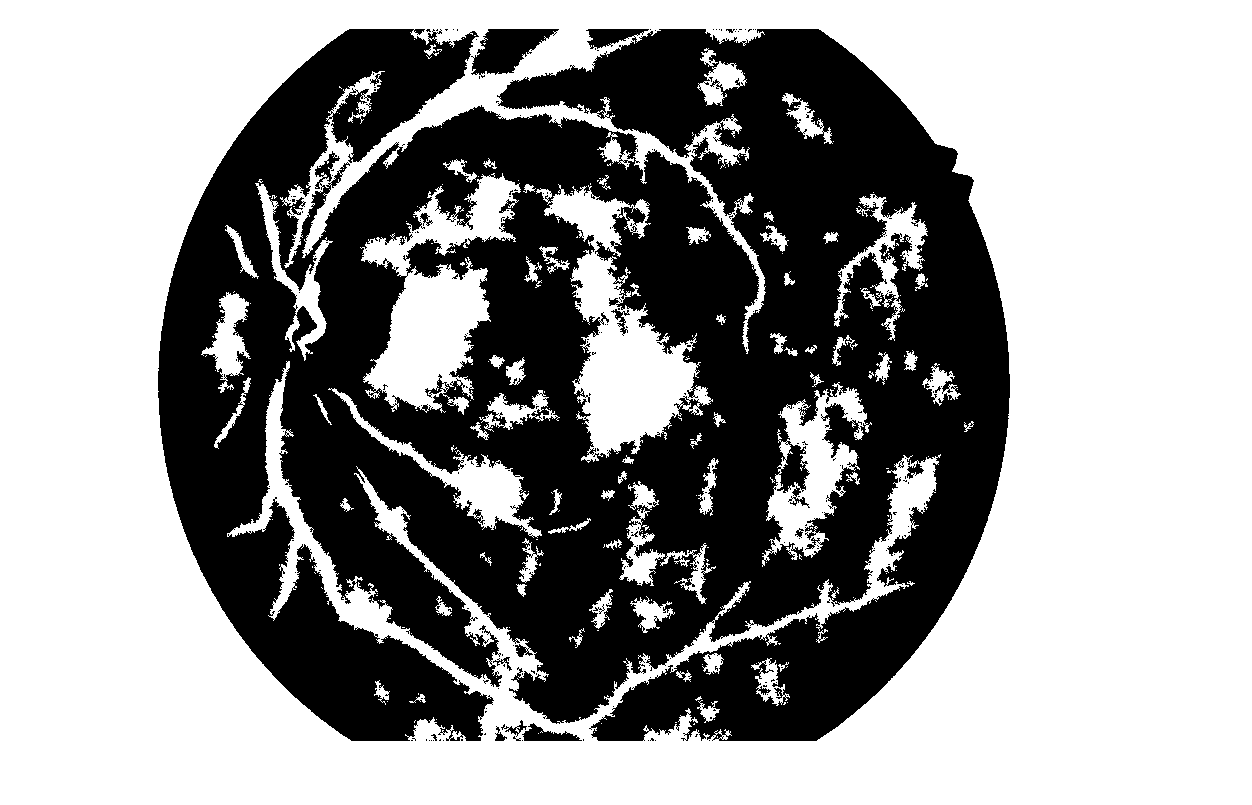

I = bwareafilt(I, 100);
imshow(I)

Smooth Image

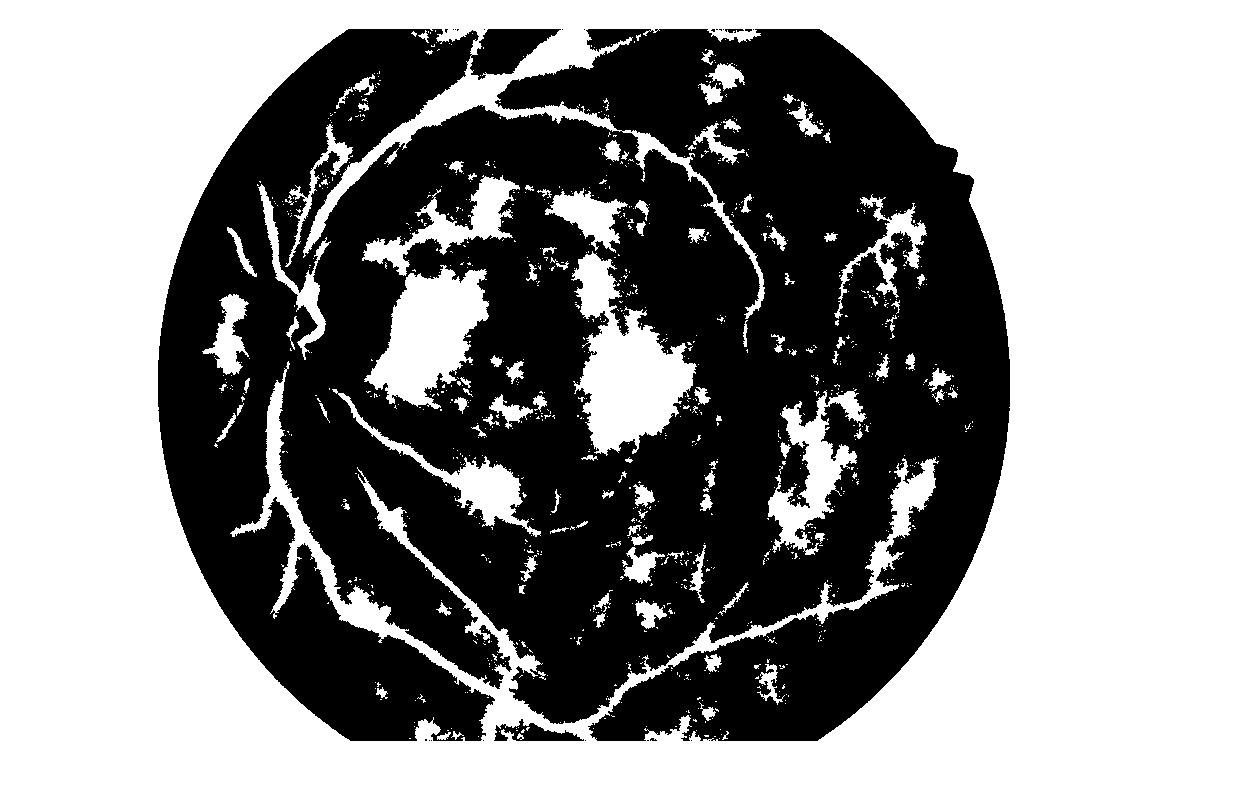

seD=strel('diamond',1);
I=imerode(I,seD);
I=imerode(I,seD);
imshow(I);

Remove patches

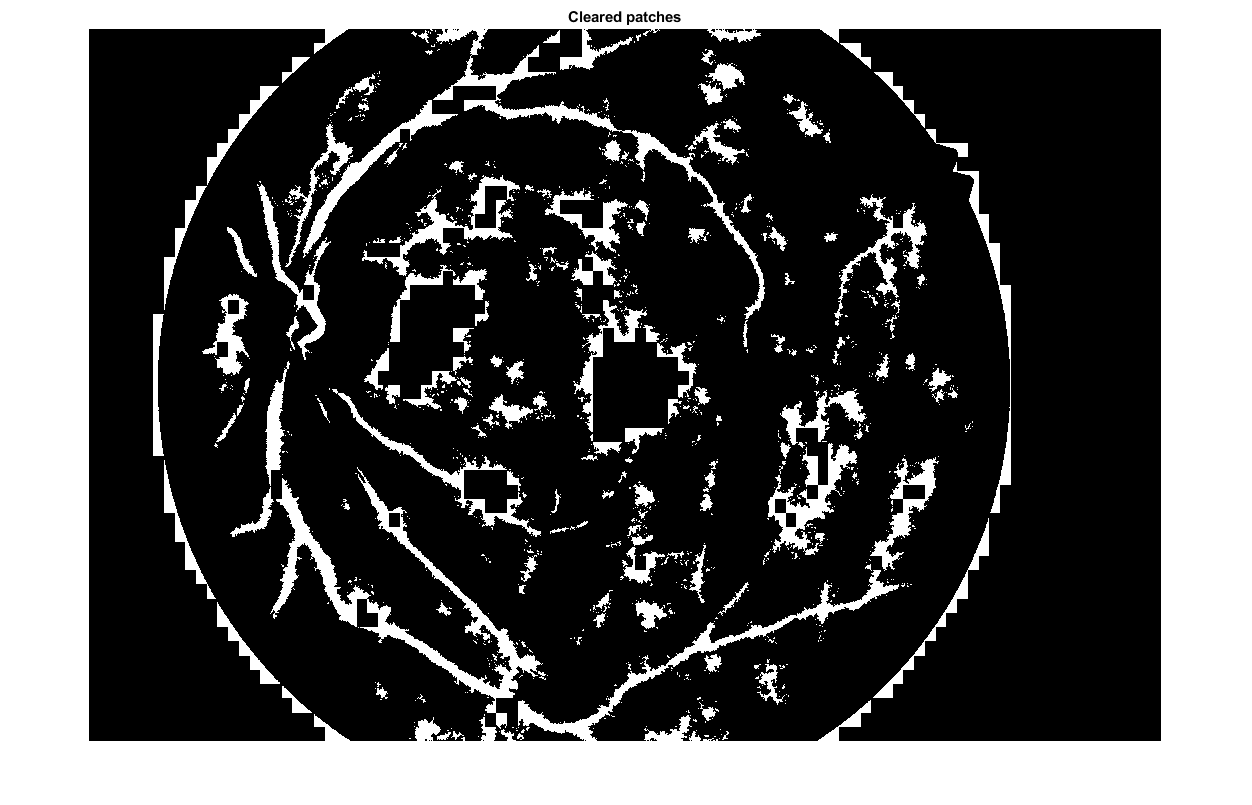

[h,w] = size(I);
I2 = I;
for i = 1:50
    for j = 1:100
        start_row = floor(1+h/50*i-h/50);
        end_row = floor(h/50*i);
        start_col = floor(1+w/100*j-w/100);
        end_col = floor(w/100*j);
        average = mean(I(start_row:1:end_row,start_col:1:end_col));
        if average > 0.8
            I2(start_row:1:end_row,start_col:1:end_col) = 0;
        end
    end
end
imshow(I2)
title('Cleared patches')

I = I2;

Image for reference:

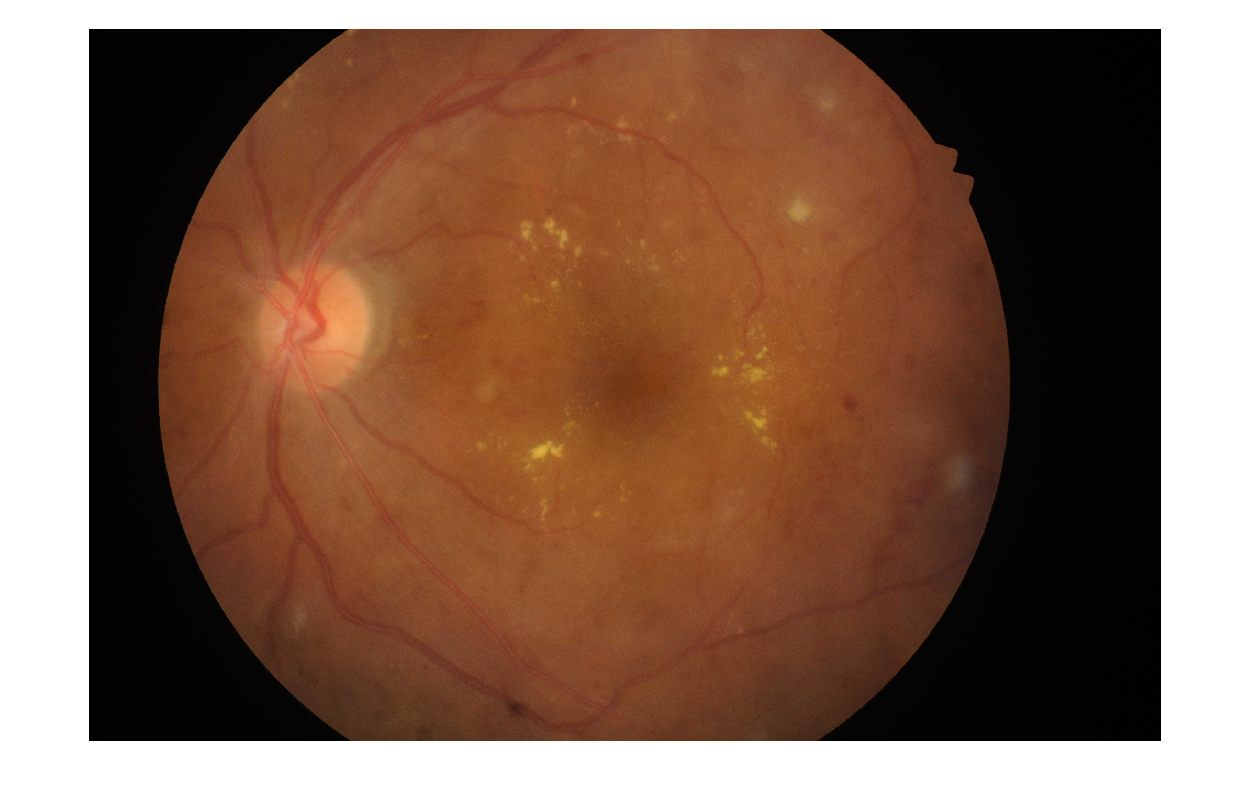

imshow(image)